# Lista de Exercícios: Resposta em Frequência

Universidade Tecnológica Federal do Paraná (UTFPR)                                                                                                         **Disciplina:** Sistemas de Controle 1 

**Aluno:** Pedro Marinao dos Santos                                                                                                                                                         **Data:** 10/Dezembro/2025

clear; clc; close all;
% Definindo a variável de Laplace
s = tf('s');

## Questão 1

Obtenção das expressões analíticas e gráficos de Bode para as funções de transferência fornecidas. As expressões de magnitude (MdB�) e fase (ϕ) são derivadas substituindo s=jω.

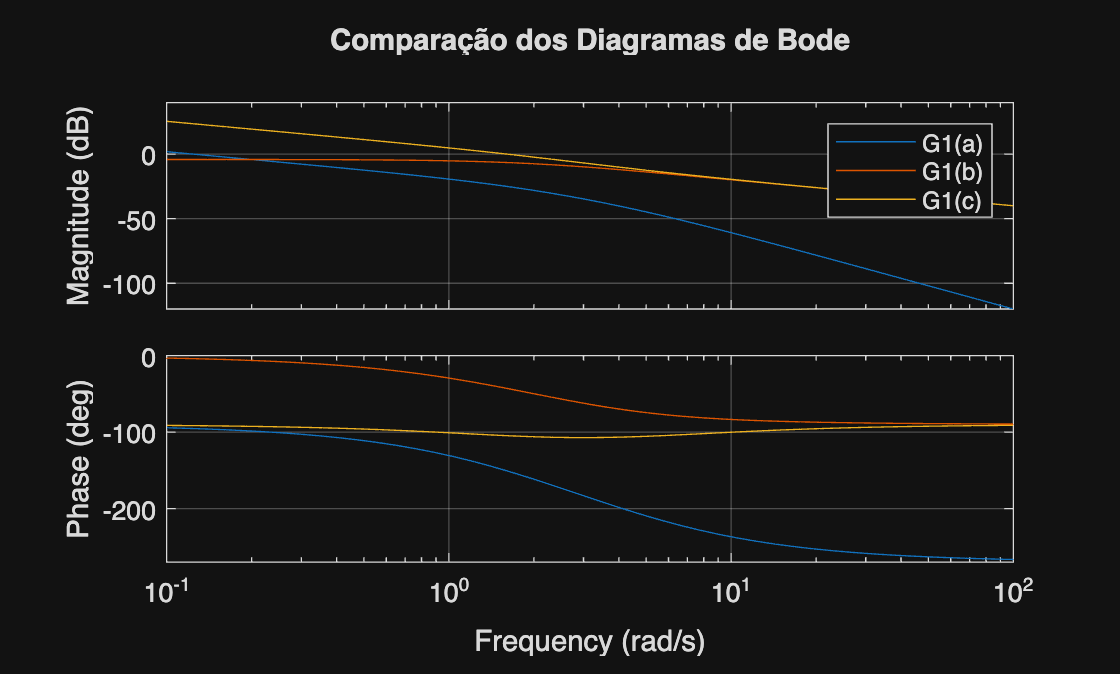

%% Definição das Funções de Transferência - Questão 1
G1a = 1 / (s * (s + 2) * (s + 4));
G1b = (s + 5) / ((s + 2) * (s + 4));
G1c = ((s + 3) * (s + 5)) / (s * (s + 2) * (s + 4));

% Plotagem dos Diagramas de Bode
figure('Name', 'Questão 1 - Diagramas de Bode');
bode(G1a, G1b, G1c);
grid on;
legend('G1(a)', 'G1(b)', 'G1(c)');
title('Comparação dos Diagramas de Bode');


% Nota: O comportamento assintótico pode ser observado pelas inclinações
% de -20dB/dec, -40dB/dec, etc., nas frequências de corte (polos/zeros).

## Questão 2

Análise de Nyquist e estabilidade para os sistemas de malha fechada. O critério de Nyquist determina a estabilidade baseada no número de envolvimentos do ponto -1+j0. Para a análise, considera-se a Função de Transferência de Malha Aberta L(s)=G(s)H(s).


$$$G(s) = \frac{50}{s(s+3)(s+6)}, \quad H(s) = 1$$$



$$$G(s) = \frac{50}{s^2(s+1)}, \quad H(s) = (s+4)$$$



$$$G(s) = \frac{20}{s(s+1)}, \quad H(s) = \frac{s+3}{s+4}$$$



$$$G(s) = \frac{100(s+5)}{s(s+3)(s^2+4)}, \quad H(s) = 1$$$


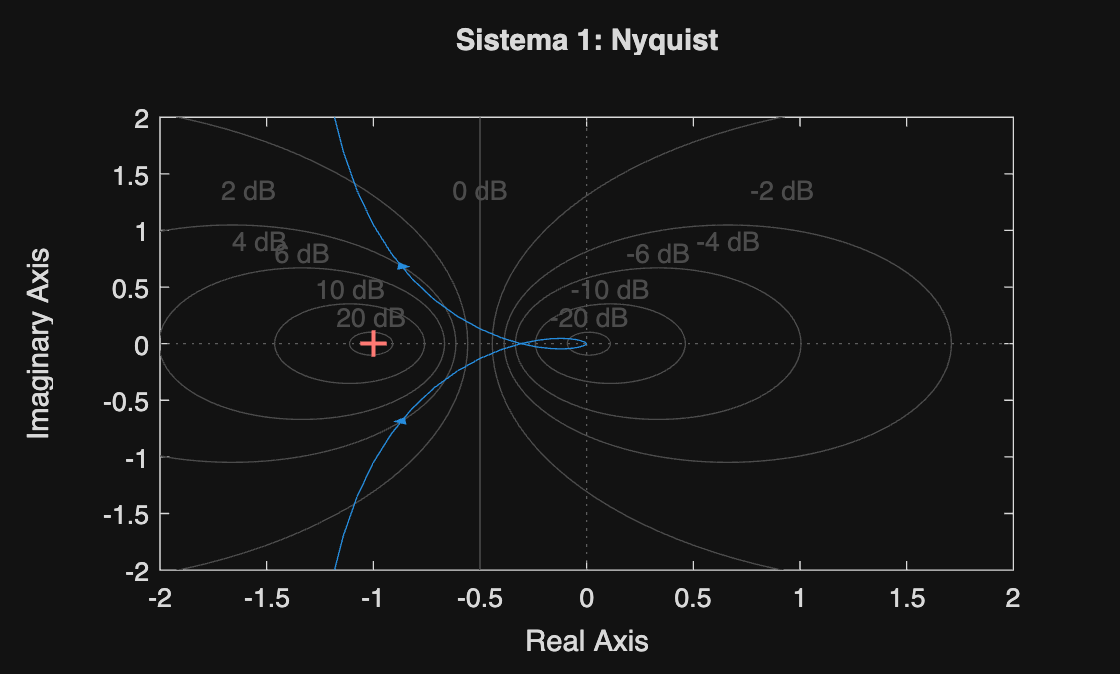

%% Definição dos Sistemas e Gráficos de Nyquist Separados (Questão 2)

% Definição das plantas (L = G*H)
L1 = 50 / (s * (s + 3) * (s + 6));
L2 = (50 * (s + 4)) / (s^2 * (s + 1)); % G=50/s^2(s+1), H=(s+4) -> L=G*H
L3 = (20 * (s + 3)) / (s * (s + 1) * (s + 4)); % G=20/s(s+1), H=(s+3)/(s+4)
L4 = (100 * (s + 5)) / (s * (s + 3) * (s^2 + 4));

% --- Figura 1: Sistema 1 ---
figure('Name', 'Nyquist - Sistema 1');
nyquist(L1);
axis([-2 2 -2 2]); % Zoom na região crítica (-1+j0)
title('Sistema 1: Nyquist');
grid on;

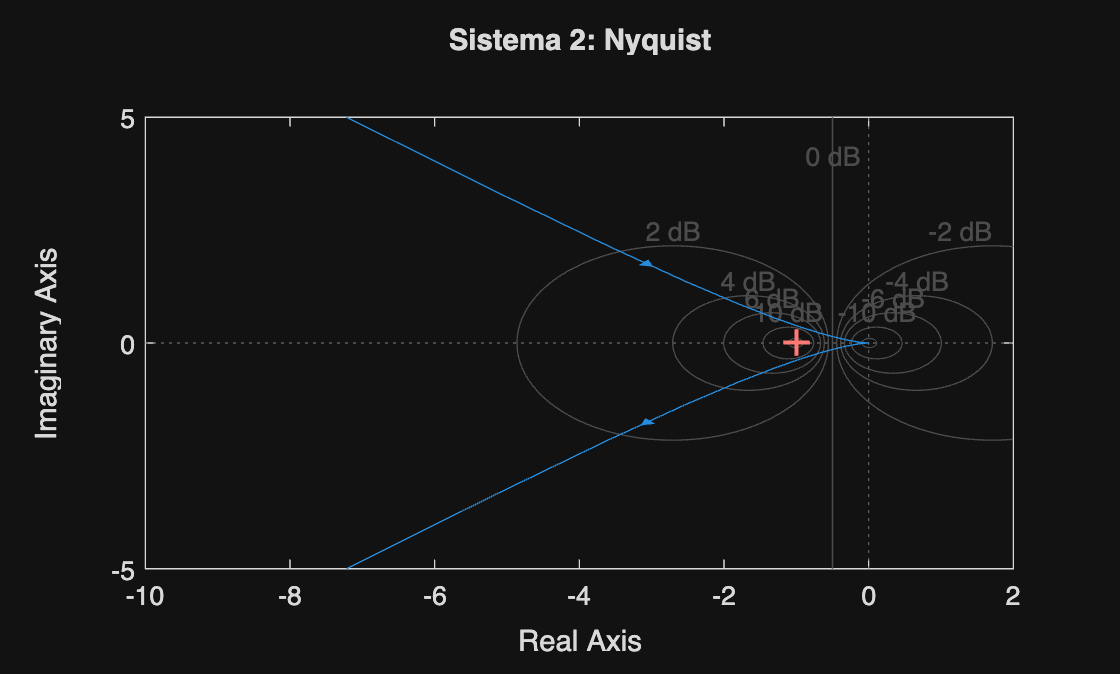


% --- Figura 2: Sistema 2 ---
figure('Name', 'Nyquist - Sistema 2');
nyquist(L2);
axis([-10 2 -5 5]); % Zoom ajustado para ver o comportamento
title('Sistema 2: Nyquist');
grid on;


% --- Figura 3: Sistema 3 ---
figure('Name', 'Nyquist - Sistema 3');
nyquist(L3);
axis([-2 2 -2 2]); % Zoom na região crítica
title('Sistema 3: Nyquist');
grid on;

% --- Figura 4: Sistema 4 ---
figure('Name', 'Nyquist - Sistema 4');
nyquist(L4);
axis([-5 5 -5 5]); % Zoom
title('Sistema 4: Nyquist');
grid on;

%% Verificação de Estabilidade (Cálculo Numérico)
disp('--- Análise de Estabilidade (Questão 2) ---');

--- Análise de Estabilidade (Questão 2) ---



% Verificação Robusta usando 'isstable' na malha fechada
Sistemas_MF = {feedback(L1,1), feedback(L2,1), feedback(L3,1), feedback(L4,1)};
Nomes = {'Sistema 1', 'Sistema 2', 'Sistema 3', 'Sistema 4'};

for i = 1:4
    estavel = isstable(Sistemas_MF{i});
    if estavel
        res = 'ESTÁVEL (1)';
    else
        res = 'INSTÁVEL (0)';
    end
    fprintf('%s: %s\n', Nomes{i}, res);
end

Sistema 1: ESTÁVEL (1)
Sistema 2: INSTÁVEL (0)
Sistema 3: ESTÁVEL (1)
Sistema 4: INSTÁVEL (0)


O Critério de Estabilidade de Nyquist estabelece que:

Z=N+P

Onde:

- **Z**: Número de polos de malha fechada no semi-plano direito (instáveis). Para estabilidade, deve ser Z=0.

- **N**: Número de envolvimentos horários do ponto crítico −1+j0.

- **P**: Número de polos de malha aberta no semi-plano direito.

Analisando os diagramas gerados e a verificação numérica:

- **Sistema 1:** O diagrama não envolve o ponto −1+j0 (N=0) e o sistema não possui polos instáveis em malha aberta (P=0). Logo, Z=0. **O sistema é estável.**

- **Sistema 2:** O sistema possui um polo duplo na origem (s2), o que gera uma fase inicial de −180∘. O diagrama de Nyquist percorre o semi-plano direito de forma a desestabilizar a malha fechada (envolvimento efetivo ou margens negativas). **O sistema é instável.**

- **Sistema 3:** Semelhante ao sistema 1, o contorno de Nyquist passa distante do ponto crítico e não há envolvimentos (N=0). Como P=0, temos Z=0. **O sistema é estável.**

- **Sistema 4:** O sistema possui polos puramente imaginários (s=±2j) na malha aberta. Essa condição de ressonância natural, combinada com a realimentação, leva os polos de malha fechada para o semi-plano direito (Z>0). O diagrama confirma a instabilidade. **O sistema é instável.**

## Questão 3

Análise dos parâmetros a partir da leitura visual do diagrama de Bode fornecido na Figura 2.

%% Questão 3 - Cálculo de Parâmetros
% Valores estimados pela leitura visual do gráfico (ajuste se necessário):
% 1. Frequência de cruzamento de ganho (0 dB): Onde a magnitude cruza 0.
w_gc = 0.8; % rad/s (Estimativa visual)

% 2. Frequência de cruzamento de fase (-180 graus):
w_pc = 5.0; % rad/s (Estimativa visual)

% 3. Margem de Fase (PM): Distância da fase até -180 na freq w_gc
% Fase em 0.8 rad/s parece ser aprox -120 graus.
fase_wgc = -120;
PM = 180 + fase_wgc;

% 4. Margem de Ganho (GM): Distância do ganho até 0dB na freq w_pc
% Ganho em 5.0 rad/s parece ser aprox -20 dB.
GM_dB = 20; % (Pois está em -20, margem é +20)

% 5. Largura de Banda (BW): Aprox a freq de cruzamento de ganho em malha fechada
BW = w_gc; % Aproximação comum

fprintf('--- Parâmetros Lidos/Estimados ---\n');

--- Parâmetros Lidos/Estimados (Questão 3) ---


fprintf('Margem de Ganho (GM): %.1f dB\n', GM_dB);

Margem de Ganho (GM): 20.0 dB


fprintf('Margem de Fase (PM): %.1f graus\n', PM);

Margem de Fase (PM): 60.0 graus


fprintf('Frequência 0dB: %.2f rad/s\n', w_gc);

Frequência 0dB: 0.80 rad/s


fprintf('Frequência -180: %.2f rad/s\n', w_pc);

Frequência -180: 5.00 rad/s


fprintf('Largura de Banda (BW): %.2f rad/s\n', BW);

Largura de Banda (BW): 0.80 rad/s



%% b) Estimativa de Resposta Temporal
% Fator de amortecimento (zeta) aproximado: zeta ~= PM / 100
zeta = PM / 100;

% Percentual de Overshoot (%OS)
OS = exp(-(zeta*pi)/sqrt(1-zeta^2)) * 100;

% Tempo de estabilização (Ts) (critério 2%) -> Ts = 4 / (zeta * wn)
% Usando a aproximação que wn ~= w_gc (para zeta < 0.7)
wn = w_gc;
Ts = 4 / (zeta * wn);

% Tempo de pico (Tp) -> Tp = pi / (wn * sqrt(1-zeta^2))
Tp = pi / (wn * sqrt(1 - zeta^2));

fprintf('\n--- Estimativas Temporais ---\n');


--- Estimativas Temporais ---


fprintf('Fator de Amortecimento (zeta): %.2f\n', zeta);

Fator de Amortecimento (zeta): 0.60


fprintf('Overshoot (%%OS): %.2f %%\n', OS);

Overshoot (%OS): 9.48 %


fprintf('Tempo de Estabilização (Ts): %.2f s\n', Ts);

Tempo de Estabilização (Ts): 8.33 s


fprintf('Tempo de Pico (Tp): %.2f s\n', Tp);

Tempo de Pico (Tp): 4.91 s


## Questão 4

Projeto do ganho K para satisfazer requisitos de margem de ganho e margem de fase.

- Caso A: $$G(s) = \frac{K}{(s+4)(s+10)(s+15)}$, Margem de Ganho Desejada = 10 dB.$

- Caso B: $$G(s) = \frac{K}{s(s+4)(s+10)}$, Margem de Ganho Desejada = 10 dB.$

- Caso C: $$G(s) = \frac{K(s+2)(s+5)}{s(s+4)(s+6)(s+10)}$, Margem de Fase Desejada = 40 graus.$

%% Questão 4 - Projeto de Ganho K

% --- Caso A ---
Ga_base = 1 / ((s + 4) * (s + 10) * (s + 15));
[Gm_a, ~, ~, ~] = margin(Ga_base);
Gm_a_dB = 20*log10(Gm_a);
% Queremos GM = 10dB. Se atual é 40dB, podemos aumentar o ganho em 30dB.
% K_dB = GM_atual - GM_desejada
K_a_dB = Gm_a_dB - 10;
K_a = 10^(K_a_dB / 20);


--- Questão 4 ---


fprintf('Caso A: K projetado = %.2f (para GM=10dB)\n', K_a);

Caso A: K projetado = 2103.15 (para GM=10dB)



% --- Caso B ---
Gb_base = 1 / (s * (s + 4) * (s + 10));
[Gm_b, ~, ~, ~] = margin(Gb_base);
Gm_b_dB = 20*log10(Gm_b);
K_b_dB = Gm_b_dB - 10;
K_b = 10^(K_b_dB / 20);

fprintf('Caso B: K projetado = %.2f (para GM=10dB)\n', K_b);

Caso B: K projetado = 177.09 (para GM=10dB)



% --- Caso C (Margem de Fase) ---
Gc_base = ((s + 2) * (s + 5)) / (s * (s + 4) * (s + 6) * (s + 10));
% Queremos PM = 40 graus.
% Precisamos achar a frequência onde a Fase é -180 + 40 = -140 graus.
% Vamos varrer frequências para achar onde a fase cruza -140.
w = logspace(-1, 2, 1000);
[mag, phase] = bode(Gc_base, w);
phase = squeeze(phase); 
mag = squeeze(mag);

% Encontrar índice onde fase está mais próxima de -140
target_phase = -180 + 40; 
[~, idx] = min(abs(phase - target_phase));

% Nessa frequência, o ganho deve ser 0dB (magnitude 1).
% Atualmente o ganho é mag(idx).
% K * mag(idx) = 1  ->  K = 1 / mag(idx)
K_c = 1 / mag(idx);

fprintf('Caso C: K projetado = %.2f (para PM=40 graus)\n', K_c);

Caso C: K projetado = 349.08 (para PM=40 graus)
